Problem 1

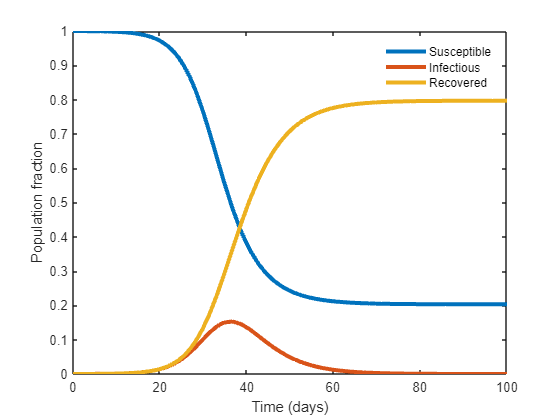

[t1, y1] = res1(.025);
figure();
tmph=plot(t1,y1);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
tmplh = legend('Susceptible','Infectious','Recovered');
legend('boxoff');

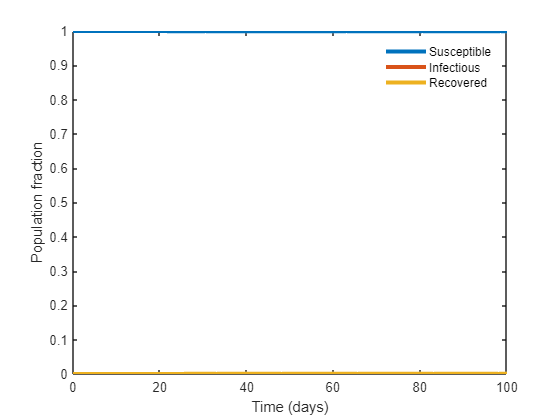


[t2, y2] = res1(.01); 
figure();
tmph=plot(t2,y2);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
tmplh = legend('Susceptible','Infectious','Recovered');
legend('boxoff');

The disease is expected to spread with its original parameters. However, if you set p to .01, then the disease does not spread. This is evident in the plot, as the population fraction for susceptible and recovered stays the same over time.

Problem 2

[t3,y3] = res2(.5, .4);

Strength (R0): 1.250000e+00
Expected Speed (r): 1.000000e-01
Estimated Speed (slope): 9.977560e-02


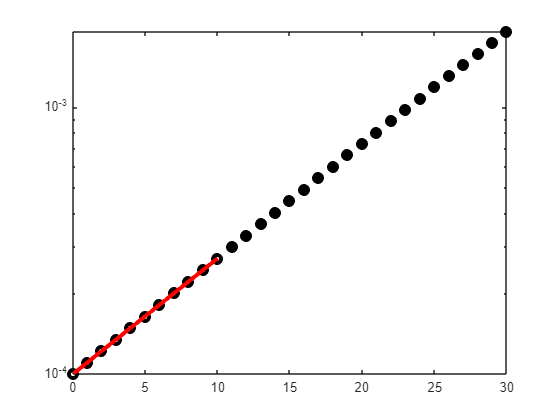

tmpi=find(t3>10);
tmph=semilogy(t3(tmpi),y3(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');


[t4,y4] = res2(1, .5);

Strength (R0): 2
Expected Speed (r): 5.000000e-01
Estimated Speed (slope): 4.953926e-01


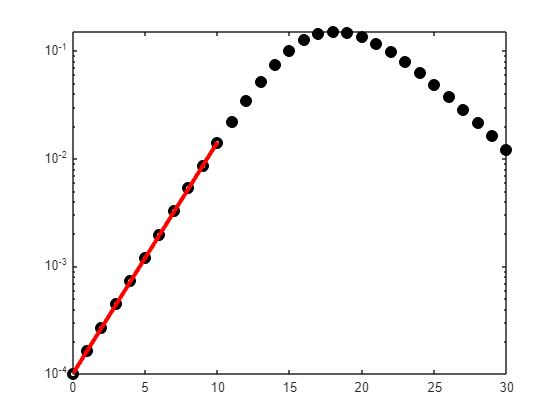

tmpi=find(t4>10);
tmph=semilogy(t4(tmpi),y4(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');


[t5,y5] = res2(.25, .5);

Strength (R0): 5.000000e-01
Expected Speed (r): -2.500000e-01
Estimated Speed (slope): -2.500413e-01


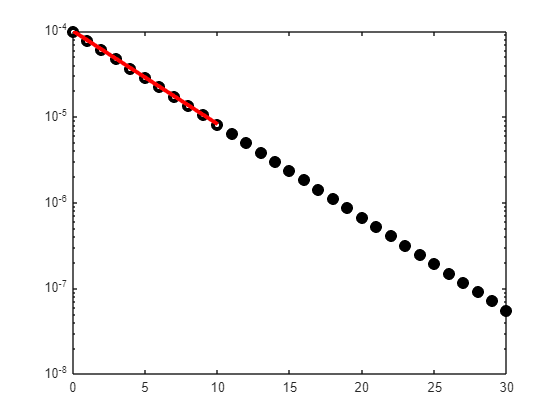

tmpi=find(t5>10);
tmph=semilogy(t5(tmpi),y5(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');


[t6,y6] = res2(.75, .25);

Strength (R0): 3
Expected Speed (r): 5.000000e-01
Estimated Speed (slope): 4.973748e-01


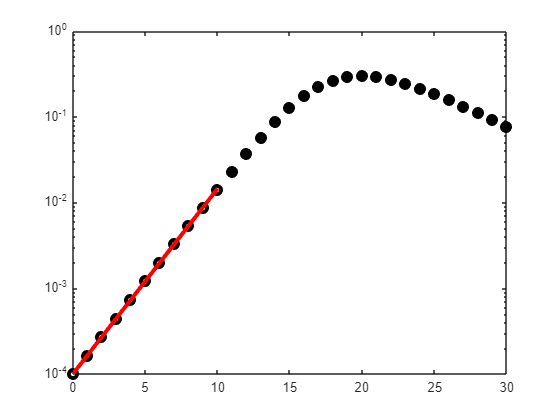

tmpi=find(t6>10);
tmph=semilogy(t6(tmpi),y6(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');

For each of the four parameter sets, the expected and estimated speeds roughly match. For example, for the first set of parameters (beta = .5, gamma = .4), the strength (R0) is equal to 1.25, and the expected speed is .1. The slope measured on the the graph equals .00978, which is roughly equal to .1, confirming that the plot matches the expected results.

Problem 3

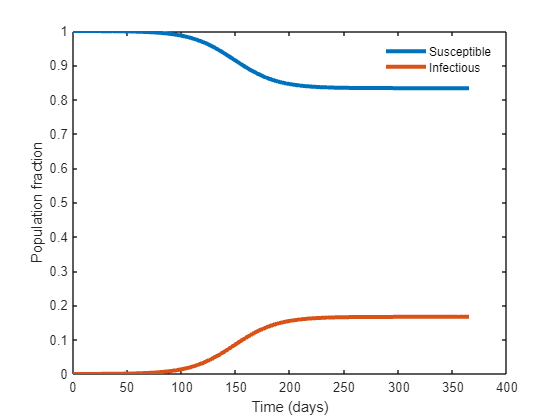

pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.025; % Probability of infectious contact
pars.beta = .3; % Transmission rate
pars.gamma = .25; % Recovery rate (days^-1)
pars.N = 10000;
pars.R0 = (pars.N*pars.beta)/pars.gamma;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

[t7,y7]=ode45(@(t,y) si_model(t,y,pars),[0 365],[pars.S0 pars.I0]/pars.N);
figure();
tmph=plot(t7,y7);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
tmplh = legend('Susceptible','Infectious');
legend('boxoff');

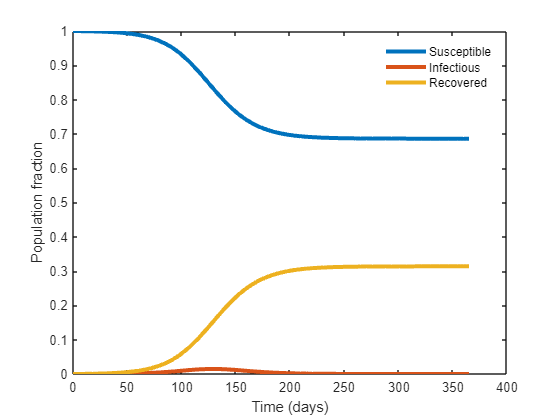


[t8,y8]=ode45(@(t,y) sir_model(t,y,pars),[0 365],[pars.S0 pars.I0 0]/pars.N);
figure();
tmph=plot(t8,y8);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
tmplh = legend('Susceptible','Infectious','Recovered');
legend('boxoff');

For both the SI and SIR models, the plots roughly follow the same shape except for a few key differences. For the SIR model, the fraction of susceptible and recovered individuals roughly follows the same shape as the susceptible and infected indivduals in the SI model. However, the proportion of susceptible and recovered individuals in the SIR model after 365 days is .7 and .3, respectively, while in the SI model, the proportion of susceptible and infected individuals is .8 and .2, respectively. However, in both models, the individuals start to drift towards this point at around the same time.

Problem 4

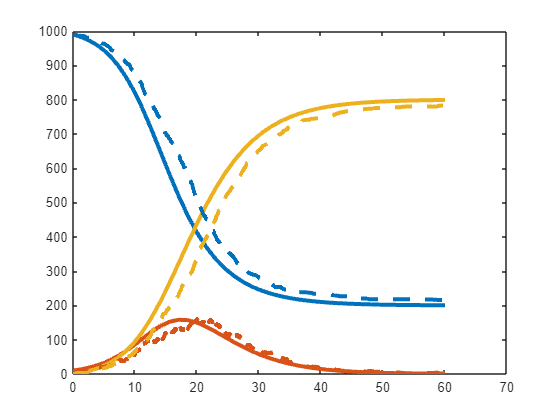

pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.025; % Probability of infectious contact
pars.beta = pars.c*pars.p; % Transmission rate
pars.gamma = 1/4; %
pars.tf=60;
pars.R0 = pars.beta/pars.gamma;
pars.N = 1000;
pars.I0= 10;
pars.S0= pars.N-pars.I0;

% Run the ODE model
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0 pars.tf],[pars.S0 pars.I0 0]/pars.N);
tmph=plot(t,pars.N*y);
set(tmph,'linewidth',3);
hold on
% Run the stochastic model
[tsim,ysim]=stochsim_SIR([0 pars.tf],[pars.S0 pars.I0 0],pars);
tmphsim=plot(tsim,ysim,'--');
set(tmphsim,'linewidth',3);
% Color the lines the same way (where dashes are for stochastic)
for i=1:3
set(tmphsim(i),'color',get(tmph(i),'color'));
end

Modified code: 

% infrate = (pars.beta*ycur(1)*ycur(2))/pars.N;
% recrate = pars.gamma*ycur(2);

% if (rand<(infrate/totrate)) % infection
%     ycur(1) = ycur(1) - 1;
%     ycur(2) = ycur(2) + 1;
% else % recovery
%     ycur(2) = ycur(2) - 1;
%     ycur(3) = ycur(3) + 1;
% end

Compared to the deterministic model, the stochastic model are roughly the same shape wise. However, the number of susceptible individuals is a slight overestimate, while the number of recovered individuals is a slight underestimate. The number of infected individuals varies between over and under depending on the time.

Functions

function dydt = sir_model(t,y,pars)
% SIR Model
S=y(1);
I=y(2);
% The model
dSdt = -pars.beta*S*I;
dIdt = pars.beta*S*I-pars.gamma*I;
dRdt = pars.gamma*I;
dydt = [dSdt; dIdt; dRdt];
end

function dydt = si_model(t,y,pars)
% SI Model
S=y(1);
I=y(2);
% The model
dSdt = -pars.beta*S*I+pars.gamma*I;
dIdt = pars.beta*S*I-pars.gamma*I;
dydt = [dSdt; dIdt];
end

function [t,y] = stochsim_SIR(trange,y0,pars)
% Simulates an SIR model via the Gillespie algorithm
% from t0 to tf in trange given initial
% conditions in y0 = [S0 I0 R0] and parameters
% in pars. Returns time and values
% Conditions
t0=trange(1);
tf=trange(2);
t(1)=t0;
y(1,:)=y0;
tcur=t0;
ycur=y0;
ind=1;
% Model
while (tcur<tf)
% Check to see if there is an infection
if (ycur(2)==0)
ind=ind+1;
t(ind)=tf;
y(ind,:)=ycur;
break;
end
% Rates
infrate = (pars.beta*ycur(1)*ycur(2))/pars.N;
recrate = pars.gamma*ycur(2);
totrate = infrate + recrate;
dt = -1/totrate*log(rand);
tcur=tcur+dt;
% Event type
if (rand<(infrate/totrate)) % infection
ycur(1) = ycur(1) - 1;
ycur(2) = ycur(2) + 1;
else % recovery
ycur(2) = ycur(2) - 1;
ycur(3) = ycur(3) + 1;
end
ind=ind+1;
t(ind)=tcur;
y(ind,:)=ycur;
end
end

function [t,y] = res1(pval)
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = pval; % Probability of infectious contact
pars.beta = pars.c*pars.p; % Transmission rate
pars.gamma = 1/4; % Recovery rate (days^-1)
pars.N = 10000;
pars.R0 = pars.beta/pars.gamma;
pars.I0= 1;
pars.S0= pars.N-pars.I0;
% Run the model
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0 100],[pars.S0 pars.I0 0]/pars.N);
end

function [t,y] = res2(beta, gamma)
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.025; % Probability of infectious contact
pars.beta = beta; % Transmission rate
pars.gamma = gamma; % Recovery rate (days^-1)
pars.N = 10000;
pars.R0 = pars.beta/pars.gamma;
pars.I0= 1;
pars.S0= pars.N-pars.I0;
[t0,y0]=ode45(@(t,y) sir_model(t,y,pars),[0:1:10],[pars.S0 pars.I0 0]/pars.N);
% Find the slope
[p,s]=polyfit(t0,log(y0(:,2)),1);
% Plot the data and overlay the best-fit exponential
figure();
tmph=semilogy(t0,y0(:,2),'ko');
set(tmph,'linewidth',3);
hold on
tmph=semilogy(t0,exp(p(1)*t0+p(2)),'r-');
set(tmph,'linewidth',3);
% Use solid points for the future k
fprintf('Strength (R0): %d\n', pars.R0);
fprintf('Expected Speed (r): %d\n', gamma*(pars.R0-1));
fprintf('Estimated Speed (slope): %d\n', p(1));
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0:1:30],[pars.S0 pars.I0 0]/pars.N);
end